# Objective function calculations

In the following we do some calculations of the objective function and compare their outcomes and deduce some further steps.

First we import the precalculated embedding solutions

clear
addpath("functions")

load materials\small_graph_data_merged.mat emb edges
emb1 = emb;
edges1 = edges;
load materials\large_graph_data_merged.mat emb edges
emb2 = emb;
edges2 = edges;

clearvars emb edges

The embeddings are of the size **nx2**. *(see building.mlx)*

head(full(emb1))

ans =    -0.0479   -0.7204
   -0.0413   -0.6601
    0.1037   -0.1772
    0.4279   -0.0266
    0.6460    0.1736


head(full(emb2))

ans =    -0.0011   -0.0041
    0.0042   -0.0063
    0.0110    0.0039
    0.0035    0.0082
   -0.0040    0.0058


## Non-normalized objective function

Update 21-01-04: There are no longer 2 different embeddings, but the example difference depicted here still holds

We want to see which embedding does the goal of being minimal better, e.g. which procedure of computation *(see building.mlx)* is provably the sounder one. For this we look at the difference of their objective values (**ov**) we get from inserting the respective embedding into the objective function.

% ov1 = ObjF(emb1);
% ov2 = ObjF(emb2);
% ov1 - ov2
% there was a difference of around 0.0299 in our small_graph_data example

Apparently, the second **ov** is a little bit better than the first in respect to minimizing. As it was calculated by means of the method matlab does encourage, namely the **A\b **call, we use this command for further calculations of embeddings instead of the call of **inv()**. For now we take the second embedding for subsequent calculations.

% emb = emb2;

Let's now test the objective function on some aspects. For this we use **fplot()**. The usage as an example is as follows:

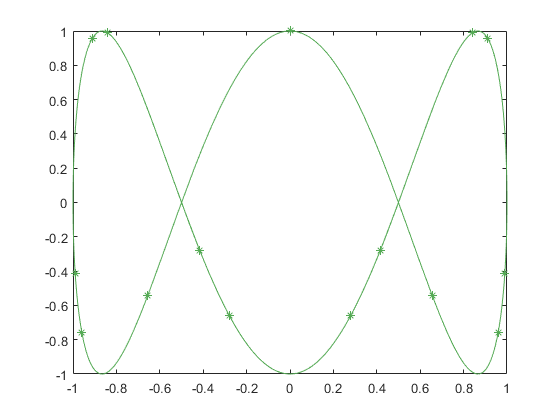

fp = fplot((@(x) sin(x)),(@(x) cos(3*x)));
fp.Color = "#5a5";
fp.Marker = "*";

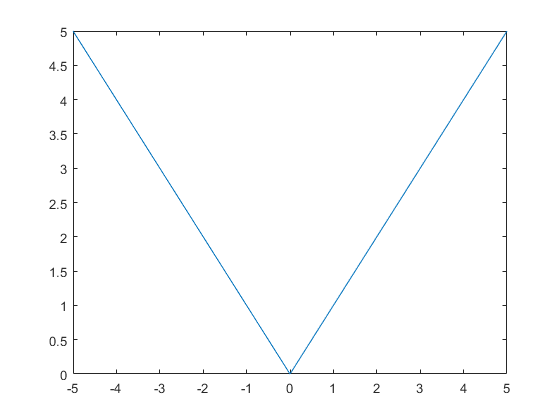

fplot(@abs)

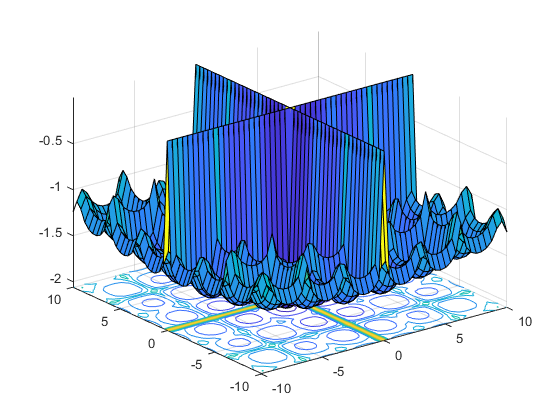

% example surfc()
f = @(X,Y) -0.0001*(abs(sin(X).*sin(Y).*exp(abs(100-sqrt(X.^2+Y.^2)/pi)))+1).^0.1;
[x,y] = meshgrid(linspace(-10, 10, 49));
figure
surfc(x, y, f(x,y))
grid on

To now plot our **ObjF()** we will need to select a specific interval. From testing we choose it as follows and plot the function in this interval.

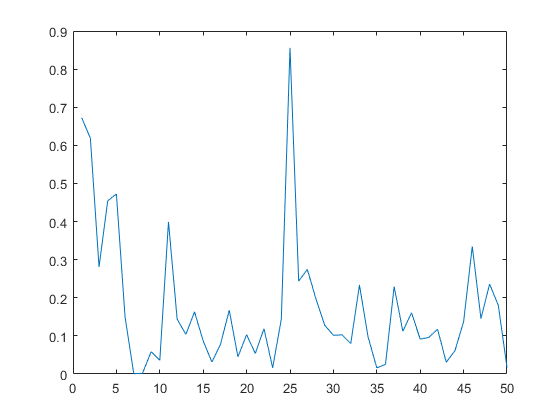

plot(abs(emb1(:,1)-emb1(:,2)))

% interval = [250 316];
af = @(x)ObjF(x.*emb1,edges1)

af = function_handle with value:
    @(x)ObjF(x.*emb1,edges1)


% example
objfff = @(x)objff(x,emb1,edges1)

objfff = function_handle with value:
    @(x)objff(x,emb1,edges1)


objfff([1 2])

ans = 	1.0e+03 *

    5.6277    7.7430


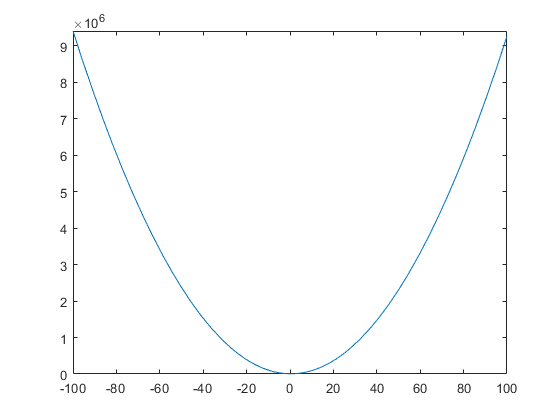

fplot(objfff,[-100 100]);

We notice that the **ov** gets minimal for a scaling factor of around **283**. From this we can conclude that the unscaled embedding is not optimal. 

Update 2021-01-06: minimal **ov **is now around **0.37**?!

% TODO

As to why this is the case we do have still work to do.

## Normalized objective function

While the non-normalized OF does give varying, but still unexpected **ov's**, the normalized OF on the other hand returns regardless of scaling of the embedding the same **ov's**. This is no surprise as the concept of normalization is exactly this disconnection from scaling.

ov1 = ObjFN(emb1);
ov2 = ObjFN(emb1*100);
ov1 - ov2

ans =     1.819e-12


## Functions

function result = objff(x,emb,edges)
    result = x;
    count = 0;
    for i = x
        count = count + 1;
        result(count) = ObjF(i*emb,edges);
    end
end

% returns the first 5 elements of a given matrix
function cm = head(mat) 
    cm = mat(1:5,:);
end